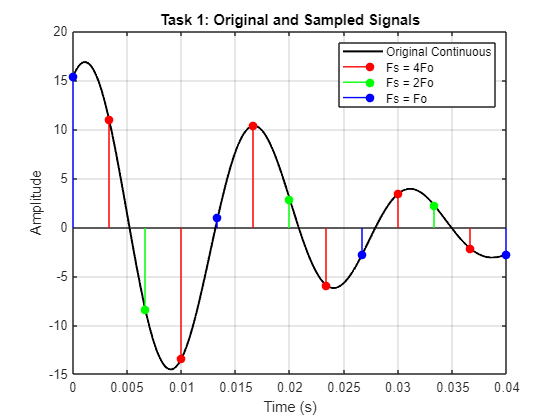

% EET 3370: DIGITAL SIGNAL PROCESSING
% LAB 1: Sampling, Multirate Processing, Aliasing & Reconstruction
% GROUP MEMBERS:
% 1. JOSHUA MUTHENYA WAMBUA   EG209/109705/22
% 2. AKALA DALVAN             EG209/109726/22

clear; clc; close all;

%% Task 1: Demonstrating Sampling at Different Rates
% A continuous‐time signal x(t) was defined as a sum of sinusoids:
%   x(t) = 10 cos(120πt) + 5 sin(100πt + 30°) + 4 sin(150πt + 45°)
% Its highest frequency component Fo = 75 Hz (from 150π → 75 Hz).
t_cont = linspace(0, 3/75, 1000);  
x_cont = 10*cos(120*pi*t_cont) + ...
         5*sin(100*pi*t_cont + deg2rad(30)) + ...
         4*sin(150*pi*t_cont + deg2rad(45));

% Sampling rates: 4Fo, 2Fo, and Fo
Fo = 75;
Fs = [4*Fo, 2*Fo, Fo];
colors = ['r','g','b'];
figure('Name','Task 1: Sampling at 4Fo, 2Fo, and Fo','NumberTitle','off');
plot(t_cont, x_cont, 'k', 'LineWidth', 1.5); hold on;

for k = 1:length(Fs)
    ts = 0:1/Fs(k):3/Fo;
    xs = 10*cos(120*pi*ts) + ...
         5*sin(100*pi*ts + deg2rad(30)) + ...
         4*sin(150*pi*ts + deg2rad(45));
    stem(ts, xs, colors(k), 'filled');
end

legend('Original Continuous','Fs = 4Fo','Fs = 2Fo','Fs = Fo');
xlabel('Time (s)'); ylabel('Amplitude');
title('Task 1: Original and Sampled Signals');
grid on;


% Discussion:
% We observed that sampling at 4Fo perfectly captured the waveform.
% At 2Fo, some distortion began to appear at peaks.
% Sampling at Fo produced clear aliasing, demonstrating violation of Nyquist.

fprintf('Task 1 completed: shown sampling at %d, %d, and %d Hz.\n', Fs);

Task 1 completed: shown sampling at 300, 150, and 75 Hz.


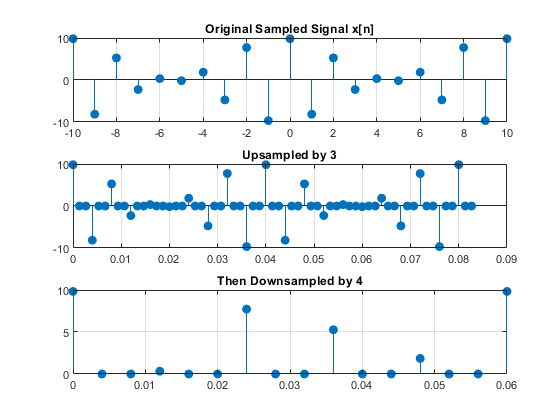


%% Task 2: Upsampling by 3 and Downsampling by 4
% Original discrete‐time signal x[n] = 10 cos(250π n/Fs) + 5 sin(200π n/Fs)
Fs2 = 250;  
n = -10:10;
t_n = n/Fs2;
x_n = 10*cos(250*pi*t_n + deg2rad(60)) + 5*sin(200*pi*t_n + deg2rad(75));

% Upsample by 3 (insert two zeros between samples)
x_up = upsample(x_n, 3);

% Downsample upsampled signal by 4 (decimate)
x_down = downsample(x_up, 4);

% Time vectors for plotting
t_up = (0:length(x_up)-1)/(Fs2*3);
t_down = (0:length(x_down)-1)/Fs2;

figure('Name','Task 2: Multirate Processing','NumberTitle','off');
subplot(3,1,1);
stem(n, x_n, 'filled'); title('Original Sampled Signal x[n]'); grid on;

subplot(3,1,2);
stem(t_up, x_up, 'filled'); title('Upsampled by 3'); grid on;

subplot(3,1,3);
stem(t_down, x_down, 'filled'); title('Then Downsampled by 4'); grid on;


% Discussion:
% Upsampling inserted zeros, increasing sample density but not adding new information.
% Downsampling removed most samples, reducing resolution and altering waveform shape.

fprintf('Task 2 completed: upsampled by 3 and downsampled by 4.\n');

Task 2 completed: upsampled by 3 and downsampled by 4.


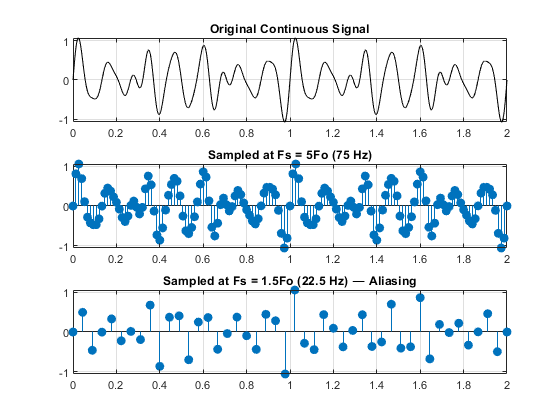


%% Task 3: Sampling and Aliasing Effects
% Continuous‐time signal with max component Fo = 15 Hz:
%   x(t) = 0.5 sin(14πt) + 1/3 sin(18πt) + 1/5 sin(24πt) + 1/7 sin(30πt)
Fo3 = 15;
t3 = 0:0.001:2;
x3 = 0.5*sin(14*pi*t3) + (1/3)*sin(18*pi*t3) + ...
     (1/5)*sin(24*pi*t3) + (1/7)*sin(30*pi*t3);

% Case i: Fs = 5Fo3 → no aliasing expected
Fs3a = 5*Fo3;
ts3a = 0:1/Fs3a:2;
x3a = 0.5*sin(14*pi*ts3a) + (1/3)*sin(18*pi*ts3a) + ...
      (1/5)*sin(24*pi*ts3a) + (1/7)*sin(30*pi*ts3a);

% Case ii: Fs = 1.5Fo3 → aliasing expected
Fs3b = 1.5*Fo3;
ts3b = 0:1/Fs3b:2;
x3b = 0.5*sin(14*pi*ts3b) + (1/3)*sin(18*pi*ts3b) + ...
      (1/5)*sin(24*pi*ts3b) + (1/7)*sin(30*pi*ts3b);

figure('Name','Task 3: Aliasing Demonstration','NumberTitle','off');
subplot(3,1,1);
plot(t3, x3, 'k'); title('Original Continuous Signal'); grid on;

subplot(3,1,2);
stem(ts3a, x3a, 'filled'); title('Sampled at Fs = 5Fo (75 Hz)'); grid on;

subplot(3,1,3);
stem(ts3b, x3b, 'filled'); title('Sampled at Fs = 1.5Fo (22.5 Hz) — Aliasing'); grid on;


% Discussion:
% At 75 Hz sampling, the waveform was captured faithfully.
% At 22.5 Hz, higher frequency components overlapped and aliased into lower bands.

fprintf('Task 3 completed: illustrated aliasing at Fs = %.1f Hz.\n', Fs3b);

Task 3 completed: illustrated aliasing at Fs = 22.5 Hz.


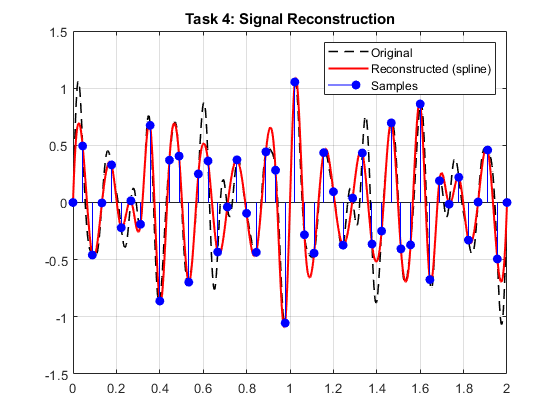


%% Task 4: Signal Reconstruction via Spline Interpolation
% Using the aliased samples from Task 3:
t_interp = 0:0.001:2;
x_interp = interp1(ts3b, x3b, t_interp, 'spline');

figure('Name','Task 4: Reconstruction via interp1','NumberTitle','off');
plot(t_interp, x3, 'k--', 'LineWidth', 1.2); hold on;
plot(t_interp, x_interp, 'r', 'LineWidth', 1.5);
stem(ts3b, x3b, 'b', 'filled');
legend('Original','Reconstructed (spline)','Samples');
title('Task 4: Signal Reconstruction'); grid on;


% Discussion:
% Spline interpolation smoothed the aliased samples but could not recover lost high-frequency detail.
% The reconstructed curve approximated original shape in low-frequency regions only.

fprintf('Task 4 completed: performed spline interpolation on aliased data.\n');

Task 4 completed: performed spline interpolation on aliased data.
